## Classification of the Antarctic sea ice cover

% Setup
clear all
clc
close all
addpath functions
addpath /Users/noahday/GitHub/CICE-analyser/processing

historydir = '/Users/noahday/maths1/wim_fixed/history/';%'/Volumes/NoahDay5TB/cases/wimoninit/history/';

a = dir([historydir '/*.nc']);
n_files = numel(a);

for i = 1:n_files
   filenames(i,:) = strcat(historydir,a(i).name);
   dirdates(i,:) = a(i).name(6:end-3);
end



% Read in data
sector = "SA";
close all
i = 6;
coords = sector_coords(sector); % (NW;NE;SW;SW) (lat,lon) %(NW;SW,NE,SE)
%for i = 1:4
i = 1;
%[lat_out(i),lon_out(i)] = lat_lon_finder(coords(i,1),coords(i,2),tlat,tlon);
%end
[swh, sector_mask] = data_format_sector(filenames(i,:),"wave_sig_ht",sector);
aice = data_format_sector(filenames(i,:),"aice",sector);
fsdrad = data_format_sector(filenames(i,:),"fsdrad",sector);
iage = data_format_sector(filenames(i,:),"iage",sector);
hi = data_format_sector(filenames(i,:),"hi",sector);
trsig = data_format_sector(filenames(i,:),"trsig",sector);


%% PCA for CICE data
% Columns are data
sector = "SA";
close all
i = 6;
[swh, sector_mask] = data_format_sector(filenames(i,:),"wave_sig_ht",sector);
aice = data_format_sector(filenames(i,:),"aice",sector);
fsdrad = data_format_sector(filenames(i,:),"fsdrad",sector);
iage = data_format_sector(filenames(i,:),"iage",sector);
hi = data_format_sector(filenames(i,:),"hi",sector);
trsig = data_format_sector(filenames(i,:),"trsig",sector);
[lat,lon] = grid_read('gx1');

%fp = data_format_sector(filenames(i,:),"peak_period",sector);
%uvel = data_format_sector(filenames(i,:),"uvel",sector);
%sigP = data_format_sector(filenames(i,:),"sigP",sector);
%Tair = data_format_sector(filenames(i,:),"Tair",sector);
%sst = data_format_sector(filenames(i,:),"sst",sector);
%Tsfc = data_format_sector(filenames(i,:),"Tsfc",sector);
%daidtd = data_format_sector(filenames(i,:),"daidtd",sector);
%daidtt = data_format_sector(filenames(i,:),"daidtt",sector);
%latitude = data_format_sector(filenames(1,:),"TLAT",sector);


afsdn_data = data_format_sector(filenames(i,:),"afsdn",sector);
NFSD = ncread(filenames(i,:),"NFSD");
for nc = 1:5
        for nf = 1:numel(NFSD)
            geom_prevalence(:,:,nf,nc) = afsdn_data(:,:,nf,nc)./aice(:,:).*NFSD(nf);
        end
end
pan_prevalence(:,:) = geom_prevalence(:,:,1,1).*100;

aice_vec = reshape(aice(sector_mask),numel(aice(sector_mask)),1);
fsdrad_vec = reshape(fsdrad(sector_mask),numel(fsdrad(sector_mask)),1);
hi_vec = reshape(hi(sector_mask),numel(hi(sector_mask)),1);
pan_vec = reshape(pan_prevalence(sector_mask),numel(pan_prevalence(sector_mask)),1);
iage_vec = reshape(iage(sector_mask),numel(iage(sector_mask)),1);
trsig_vec = reshape(trsig(sector_mask),numel(trsig(sector_mask)),1);
swh_vec = reshape(swh(sector_mask),numel(swh(sector_mask)),1);
lat_vec = reshape(lat(sector_mask),numel(lat(sector_mask)),1);
lon_vec = reshape(lon(sector_mask),numel(lon(sector_mask)),1);


clear fsdrad hi pan_prevalence geom_prevalence iage afsdn_data 

%fp_vec = reshape(fp(sector_mask),numel(fp(sector_mask)),1);
%sigP_vec = reshape(sigP(sector_mask),numel(sigP(sector_mask)),1);
%Tair_vec = reshape(Tair(sector_mask),numel(Tair(sector_mask)),1);
%sst_vec = reshape(sst(sector_mask),numel(sst(sector_mask)),1);
%Tsfc_vec = reshape(Tsfc(sector_mask),numel(Tsfc(sector_mask)),1);
%uvel_vec = reshape(uvel(sector_mask),numel(uvel(sector_mask)),1);
%daidtd_vec = reshape(daidtd(sector_mask),numel(daidtd(sector_mask)),1);
%daidtt_vec = reshape(daidtt(sector_mask),numel(daidtt(sector_mask)),1);
%latitude_vec = reshape(latitude(sector_mask),numel(latitude(sector_mask)),1);
% Select sea ice statistics
X = [aice_vec, pan_vec, hi_vec, iage_vec, fsdrad_vec,lat_vec, lon_vec]%,swh_vec]; % Ice conditions, [%,%,cm,days,m]

X = 551×7 single matrix
    0.9626    0.0087    0.4606    0.1851  837.6786  -70.1388   20.1875
    0.9615    0.0068    0.4325    0.1645  833.2347  -70.1388   21.3125
    0.9571    0.0054    0.4276    0.1589  830.1072  -70.1388   22.4375
    0.9518    0.0041    0.4005    0.1522  827.5036  -70.1388   23.5625
    0.9420    0.0029    0.3346    0.1436  824.6097  -70.1388   24.6875
    0.9049    0.0020    0.2514    0.1309  818.2881  -70.1388   25.8125
       NaN       NaN       NaN       NaN       NaN  -70.1388   26.9375
       NaN       NaN       NaN       NaN       NaN  -70.1388   28.0625
       NaN       NaN       NaN       NaN       NaN  -70.1388   29.1875
       NaN       NaN       NaN       NaN       NaN  -70.1388   30.3125


clear aice_vec pan_vec hi_vec iage_vec fsdrad_vec lat_vec lon_vec
%
%X = [swh_vec, aice_vec, fsdrad_vec, fp_vec, sigP_vec, Tair_vec, sst_vec, Tsfc_vec, hi_vec];
%X = [pan_vec, abs(daidtd_vec),abs(daidtt_vec),hi_vec,iage_vec,fsdrad_vec];
%% Clean the data
clc
clear X_new
% Step 0: removing NaNs
idx1 = isnan(X);
%idx2 = X < eps; % ND: ALL VARIABLES MUST BE STRICTLY POSITIVE
idx = logical(idx1);%;|logical(idx2);
[len, wid] = size(X);
count = 1;
for j = 1:len
    if sum(idx(j,:)) == 0
        X_new(count,:) = X(j,:);
    count  = count + 1;
    end
end
X_new_unstandard = X_new;
% Step 1: Standardization
wid = 5;
for j = 1:wid
    % Calculate mean
    mean_X(j) = mean(X_new(:,j));
    % Calculate standard deviation
    std_X(j) = std(X_new(:,j));
    % Standardise the data
    X_new(:,j) = (X_new(:,j) - mean_X(j))/std_X(j);
end

disp('X_new done')

X_new done


conFigure(40)
% Step 2: Covariance analysis
X_cov = X_new(:,1:5);
C = cov(X_cov);
close all
figure;
R = corrplot(double(X_cov),'varNames',{'aice','pan prev.','thickness','iage','fsdrad'});
conFigure(11,1)
[~, h_corrmat, h_colorbar] = plot_corrmat([],... % leave timeSeries input empty, since already calculated corrmat
    'corrmat', R,... % the correlation matrix
    'title', 'Ice conditions',... % plot title
    'labels', {'aice','pan prev.','thickness','iage','fsdrad'},... % correlation matrix cell labels
    'label_FontSize', 11,... % long labels get cutoff with larger fonts
    'outline', 1); % outline the cells (appearance improvement)

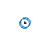


%% plotting cluster analysis
clc
close all
%PCA
figure;
[coeff,score,latent,tsquared,explained] = pca(X_cov);
% The rows of coeff contain the coefficients for the five ice variables, and its columns correspond to five principal components.
% Each column of score corresponds to one principal component. 
% The vector, latent, stores the variances of the five principal components.

% Reconstruct the centered ingredients data.
Xcentered = score*coeff';

scatter(score(:,1),score(:,2),'o')
axis equal
xlabel('1st Principal Component')
ylabel('2nd Principal Component')

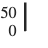


figure
bar(1:numel(explained),explained)
ylabel('$\%$ of variance explained by each principal component')

fprintf('%g percent of the variance is explained by the first two principal components', sum(explained(1:2)))

86.5964 percent of the variance is explained by the first two principal components

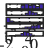


figure
for i = 1:numel(explained)
    subplot(6,1,i)
    hist(score(:,i))%,'varlabels',{'aice','pancake prev.','thickness','age','fsdrad','SWH'});
end

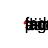


figure
biplot(coeff(:,1:2),'scores',score(:,1:2),'varlabels',{'aice','pancake prev.','thickness','iage','fsdrad'});


%% Clustering
clc
X = score(:,1:2);
close all
rng(1); % For reproducibility
[idx,C] = kmeans(X,3);

x1 = linspace(min(X(:,1)),max(X(:,1)),1000);%min(X(:,1)):0.5:max(X(:,1));
x2 = linspace(min(X(:,2)),max(X(:,2)),1000);%min(X(:,2)):0.5:max(X(:,2));
[x1G,x2G] = meshgrid(x1,x2);
XGrid = [x1G(:),x2G(:)]; % Defines a fine grid on the plot

idx2Region = kmeans(XGrid,3,'MaxIter',1,'Start',C);

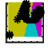


conFigure(12,1)
figure;
subplot(1,1,1);
gscatter(XGrid(:,1),XGrid(:,2),idx2Region,...
    [0,0.75,0.75;0.75,0,0.75;0.75,0.75,0],'..');
hold on;
plot(X(:,1),X(:,2),'k*','MarkerSize',5);
plotv(coeff(:,1:2))
%xlabel 'Pancake prevalance [$\%$]'; 
set(gca,'xticklabel',{[]})
ylabel 'PCA2';
xlabel 'PCA1';
legend off
%legend('Region 1','Region 2','Region 3','Data','Location','NorthEast');

hold off;

% New clustering model?


% Plot scatter with dots matching the colour of each region!




% Make worldmap with colour matching

XGrid = 1000000×2 single matrix
   -7.0437   -3.6426
   -7.0437   -3.6367
   -7.0437   -3.6308
   -7.0437   -3.6249
   -7.0437   -3.6190
   -7.0437   -3.6131
   -7.0437   -3.6072
   -7.0437   -3.6013
   -7.0437   -3.5955
   -7.0437   -3.5896



map_data = [X_new(:,end-1:end);

